# Practical 5

## Question Form

A semi-batch industrial scale reactor is adopted to carry out two irreversible elementary steps occurring in liquid phase, both exothermic and both with first order kinetics: 


$$A\to P\to S$$


A is the reactant, **P the desired product**, and S an unwanted by-product. $k_1$ and $k_2$ are the reaction rate  coefficients [$s^{-1}$], whereby the pre-exponential factors and the activation energy in the Arrhenius  equation for $k_2$  are much larger than those in that of $k_1$. Initially, there is a concentration of A equal to  400 [mol/m3] in a reactor volume of 1.9 m3 at 295 K. Then, after 1800 s, the remaining amount of reactant A is introduced into the reactor with a concentration of 1260 [mol/m3] and a volumetric flowrate of 1.043e-3 [m3/s1] at 345 K.**Compare the results with the ones obtained by adopting a batch reactor at industrial scale and with the one at lab-scale explaining the reason of the differences. **

## **Theory**

### Batch Reactor

We want to solve the system in liquid phase. Assume that the density ($\rho \;$) is constant. The reaction rate equtions for species are as follows:


$$\begin{array}{l}
\frac{{\textrm{dC}}_A }{\textrm{dt}}=-k_1 C_A \\
\frac{{\textrm{dC}}_P }{\textrm{dt}}=+k_1 C_A -k_2 C_P 
\end{array}$$


The Energy balance equation through the reactor:


$$\frac{\textrm{dT}}{\textrm{dt}}=\frac{\left\lbrack \left(-r_1 \right)\left(\Delta H_{\textrm{R1}} \right)+\left(-r_2 \right)\left(\Delta H_2 \right)+{\textrm{Ua}}_V \left(T_{\textrm{Coolant}} -T\right)\right\rbrack }{\rho C_P }\;\;\;\;\;\;,a_V =\frac{S}{V}$$


One of the huge problems for all types of reactors is *Scale-up from lab. scale to industrial scale*. Maintaining the temperature of the reactor is the other problem!

The main goal of this excercise is how to perform scale-up in a reactor!

## Data

close all, clear, clc
global E1 R k1_0 E2 k2_0 deltaH1 deltaH2 U A_v rho cp t_s
scale = "industrial"; 
rho = 1000; % kg/m3
cp = 4*1e3; %J/kg/K
U = 500; %W/m2/K
k1_0=0.5; % 1/s
k2_0=1e11; % 1/s
E1=20e3; %J/mol
E2=100e3; %J/mol
deltaH1 = -300e3; %J/mol
deltaH2 = -250e3; 
R = 8.314; % J/mol/K
t_s = 3600; % initial value: 3600 s

switch scale
    case 'lab'
    % lab scale values:
    A_v = 9.5; % 1/m
    V = 0.063; % m3
    case 'industrial'
    % industrial scale values:
    A_v = 2.6; % 1/m
    V = 6.3; % m3
end

## Initial Conditions

T0 = 295; % K
cA_0=1000; % mol/m3
cP_0 = 0;
cC_0 = 0;

## Solving Equations

tspan=[0 6000]; % seconds
[t,y] = ode23s(@batch_reactor, tspan, [cA_0 cP_0 cC_0 T0]);

## Post Processing

cA = y(:,1);
cP = y(:,2);
cC = y(:,3);
T = y(:,4);
T_h = zeros(length(t),1);
for i = 1:length(t)
    if t(i)<t_s
        T_h(i) = 345; %K
    else 
        T_h(i) = 295; %K
    end
end
Conversion = 1-cA(end)/cA_0;
Selectivity = cP(end)/(cA_0-cA(end));
Yield = Conversion*Selectivity;

## Temperature Profile

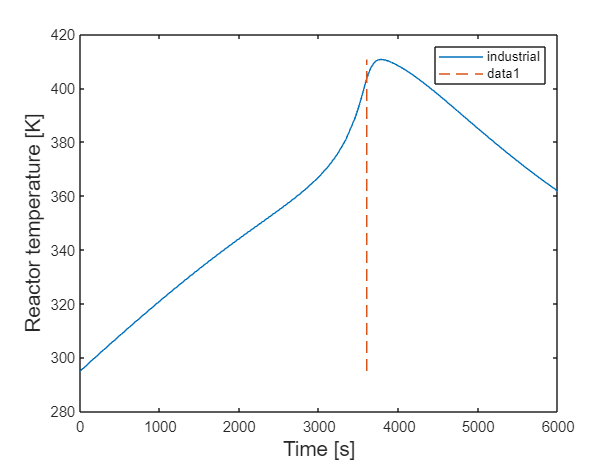

figure(1)
plot(t,T)
hold on
xlabel('Time [s]','FontSize',14)
ylabel('Reactor temperature [K]','FontSize',14)
legend(scale)

tt = [t_s, t_s];
Treact = [min(T), max(T)];

plot(tt, Treact, '--')

## Concentration Profile

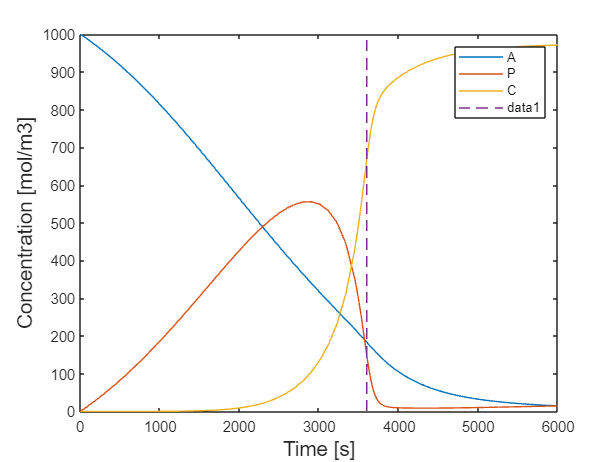

switch scale
    case 'lab'
    figure(2)
    plot(t,y(:,1:3))
    hold on
    xlabel('Time [s]','FontSize',14)
    ylabel('Concentration [mol/m3]','FontSize',14)
    legend('A','P','C')
    tt = [t_s, t_s];
    creact = [0,max(cA)];
    plot(tt, creact, '--')

    case 'industrial'
    figure(3)
    plot(t,y(:,1:3))
    hold on
    xlabel('Time [s]','FontSize',14)
    ylabel('Concentration [mol/m3]','FontSize',14)
    legend('A','P','C')
    tt = [t_s, t_s];
    creact = [0,max(cA)];
    plot(tt, creact, '--')

end

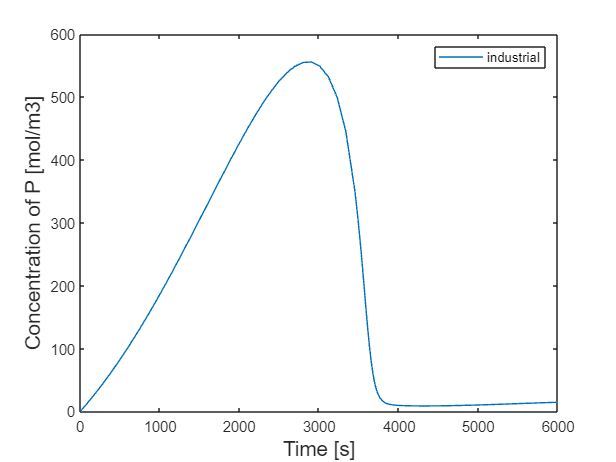

figure(4)
plot(t,cP)
hold on
xlabel('Time [s]','FontSize',14)
ylabel('Concentration of P [mol/m3]','FontSize',14)
ylim([0 600])
legend(scale)


fprintf("Conversion: %f %% \n",Conversion*100)

Conversion: 98.537622 % 


fprintf("Selectivity: %f %% \n",Selectivity*100)

Selectivity: 1.478353 % 


fprintf("Yield: %f %% \n",Yield*100)

Yield: 1.456734 % 


## Semi-Batch Reactor

## Jalal's Notes!

To compare the conversion, selectivity, and yield of a Batch reactor and a Semi-Batch reactor in two different cases of lab and industrial scale, we need to write a mass balance and an energy balance for both reactors and get the gradient of temperature and concentration of species. According to the reaction that we have ($A\to P\to S$), the P is the wanted product and S is the unwanted product. According to the text, the kinetic constant and activation energy of the second reaction is much higher than the first reaction, meaning that after that concentration of P reaches to an acceptable amount, in a high temperature it totally converts to the unwanted product of S. To control the temperature of the system, we are using a coolant jacket around the reactor. To solve the equations that we have, we need to know stochiometric coefficients, reaction rates, U, $a_V$, $\Delta H_R$, and the volumetric inlet flow rate. All of these data are given, and it said that our reaction rates are first order. Now, with solving these equations, we could get the concentration gradient of A, P, and S in the reactor, alongside of the temperature in the reactor. As we are changing from lab scale to industrial one in both of the reactors, we could see that the same selectivity and yield decrease a lot. This is due to the fact that the volume of reactor increased, more reaction is happening in the reactor and consequently the temperature is higher. As mentioned before, this would convert the P to S. to solve this problem, the best procedure is that we change the reactor from a batch to a semi-batch reactor. In this way we introducing the A to the system gradually, so the reaction rates are under control and the temperature do not increase a lot to make it possible for the second reaction to take the overall process rate. So, in the end the semi-batch reactor is the better choice when we have series reactions. The other option to increase the selectivity and yield is through changing the time that the coolant goes to the jacket. First we run the experiment to see where we have the maximum amount of P, then we adjust the cooling time around that point to reduce the temperature and do not let the P convert to S.